## **Condition Monitoring Project**

# **Damage Detection on Bearings**

Done by

**Guru Prasaath Pushparaj**

Matriculation number**: 1702033**

Data set used:** WS2324_9**

Password:  **WS2324_951419**

Email ID: **guru.pushparaj@student.uni-siegen.de**

 The outline of the project is divided into two categories.

- Analysis in Time domain

- Anallysis in Frequency domain

## **1****.Statistical features Analysis of signals in Time domain**

clc;
clear;
% clearing or emptying the values of the variables in workspace

% Gets the actual path of the directory
path = pwd;

% Using the function "fullfile" to create a variable "savepath", which saves
% the complete path to the measured data. 
% Using the variable path and the folder name, where the data is stored. 
savepath = fullfile(path,'WS2324_9');

% Using the function what which converts all the files in the location into
% a single structure x
x = what(savepath);

% Converting the structure into array using Dot and extracting only mat
% files
x = x.mat;
size = length(x);
disp(['Number of signals found in the folder : ', num2str(size)]);

Number of signals found in the folder : 3



% Declaring variables for each function instead of its own name
signal1 = x{1};
signal2 = x{2};
signal3 = x{3};

#### **Analysis of Signal 1**

Extracting features like mean, kurtosis, standard deviation, crest, skewness and quantile values

Also Box plot is been plotted to visualze the distribution of data and finding out the outliers in the signal

% Loading signal 1
% Construct the full path of the selected file
File_Path = fullfile(savepath, signal1);

% Load the data from the selected file
loadedData = load(File_Path);

% Extracting the only the datensatz details from the signal
signal_1 = loadedData.datensatz;

mean_Signal_1 = mean(signal_1) % Mean

mean_Signal_1 = -0.0268

RMS_Signal_1 = rms(signal_1) % Root mean square

RMS_Signal_1 = 2.0661

STD_Signal_1 = std(signal_1) % standard deviation

STD_Signal_1 = 2.0660

var_Signal_1 = var(signal_1) % variance

var_Signal_1 = 4.2682

skew_Signal_1 = skewness(signal_1) % skewness

skew_Signal_1 = -0.0025

crest_Signal_1 = peak2rms(signal_1) % Crest 

crest_Signal_1 = 4.8662

Kurto_Signal_1 = kurtosis(signal_1) % kurtosis

Kurto_Signal_1 = 2.9767

quant50_Signal_1 = quantile(signal_1,0.5) % Quantile for 50% of the signal

quant50_Signal_1 = -0.0271

quant95_Signal_1 = quantile(signal_1,0.95) % Quantile for 95% of the signal

quant95_Signal_1 = 3.3715

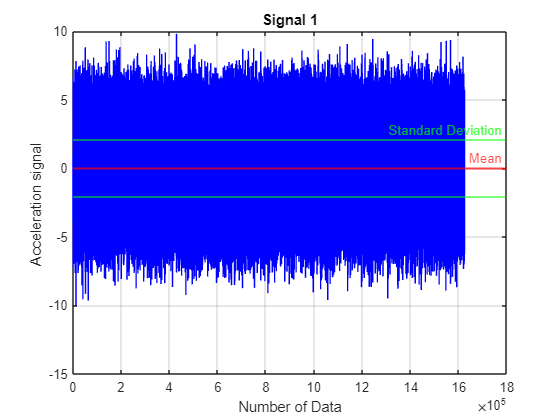


% Plotting the Signal
figure(1)
plot(signal_1, 'b');
grid on
xlabel('Number of Data');
ylabel('Acceleration signal ');
yline(mean_Signal_1,'r','Mean','LineWidth',1.5,'FontSize',10);
yline(STD_Signal_1,'g', 'Standard Deviation');
yline(-STD_Signal_1,'g');
title('Signal 1');

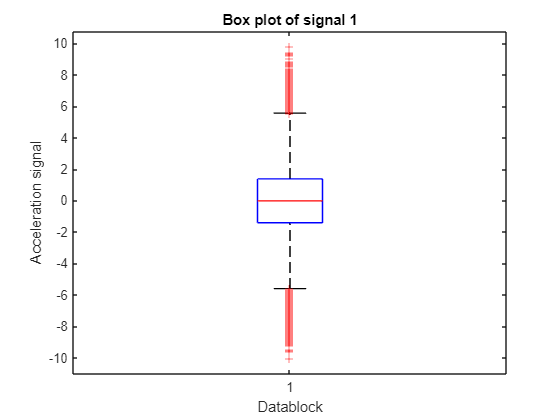


% Plotting box plot for the signal
figure(2)
boxplot(signal_1)
title('Box plot of signal 1')
xlabel('Datablock')
ylabel('Acceleration signal')

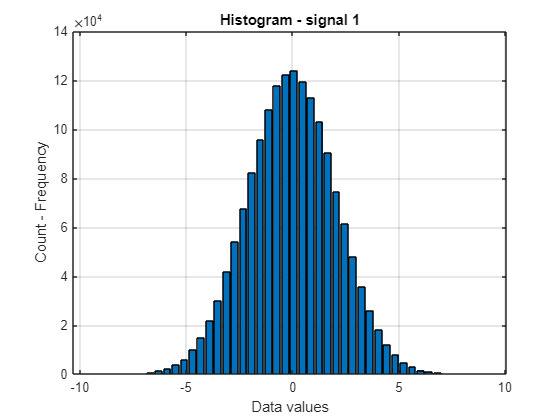



% Plotting Histogram for analysing the frequecny of value occured
figure(3);
nclasses=50;
[count_1, centre_1] = hist(signal_1, nclasses);
bar(centre_1, count_1);
grid on;
title('Histogram - signal 1');
xlabel('Data values');
ylabel('Count - Frequency');

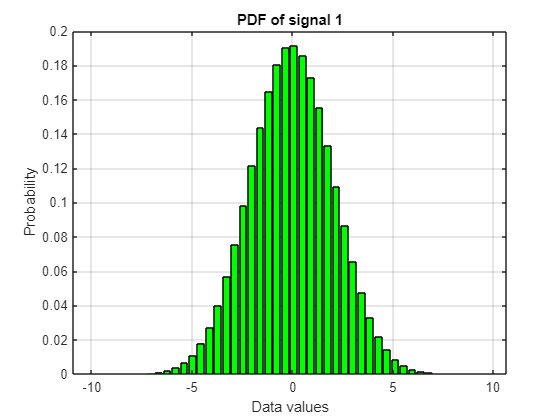


% Plotting Probability density function
figure(4);
nclasses=50;
[prop_freq_1,ks_center_1] = ksdensity(signal_1,'npoints', nclasses);
bar(ks_center_1, prop_freq_1, 'g');
grid on;
title('PDF of signal 1');
xlabel('Data values');
ylabel('Probability');

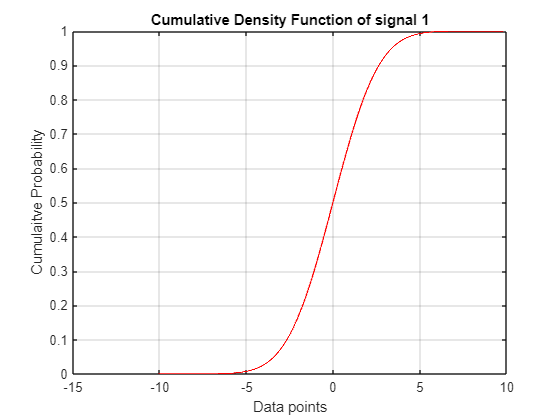


% Plotting Cumulative density function
figure(5);
[fcdf_1,xcdf_1] = ecdf(signal_1);
plot(xcdf_1,fcdf_1,'r','LineWidth',1);
grid on;
title('Cumulative Density Function of signal 1')
xlabel('Data points');
ylabel('Cumulaitve Probability');

**Analysis of Signal 2**

% Loading signal 2
% Construct the full path of the selected file
File_Path = fullfile(savepath, signal2);

% Load the data from the selected file
loadedData = load(File_Path);

% Extracting the only the datensatz details from the signal
signal_2 = loadedData.datensatz;

mean_Signal_2 = mean(signal_2) % Mean

mean_Signal_2 = -0.0363

RMS_Signal_2 = rms(signal_2) % Root mean square

RMS_Signal_2 = 4.5611

STD_Signal_2 = std(signal_2) % standard deviation

STD_Signal_2 = 4.5610

var_Signal_2 = var(signal_2) % variance

var_Signal_2 = 20.8023

skew_Signal_2 = skewness(signal_2) % skewness

skew_Signal_2 = -0.0334

crest_Signal_2 = peak2rms(signal_2) % Crest 

crest_Signal_2 = 5.6266

Kurto_Signal_2 = kurtosis(signal_2) % kurtosis

Kurto_Signal_2 = 3.1113

quant50_Signal_2 = quantile(signal_2,0.5) % Quantile for 50% of the signal

quant50_Signal_2 = -0.0151

quant95_Signal_2 = quantile(signal_2,0.95) % Quantile for 95% of the signal

quant95_Signal_2 = 7.4366

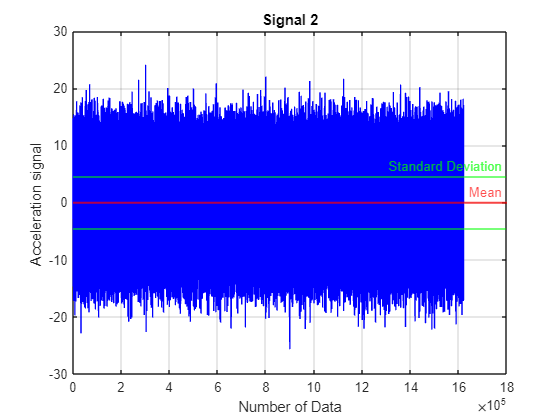


% Plotting the Signal
figure(6)
plot(signal_2, 'b');
grid on
xlabel('Number of Data');
ylabel('Acceleration signal ');
yline(mean_Signal_2,'r','Mean','LineWidth',1.5);
yline(STD_Signal_2,'g', 'Standard Deviation');
yline(-STD_Signal_2,'g');
title('Signal 2');

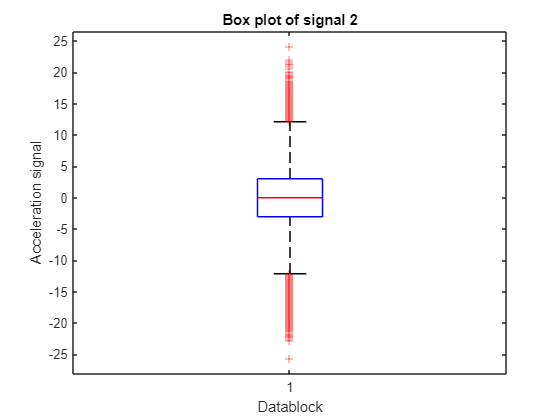


% Plotting box plot for the signal
figure(7)
boxplot(signal_2)
title('Box plot of signal 2')
xlabel('Datablock')
ylabel('Acceleration signal')

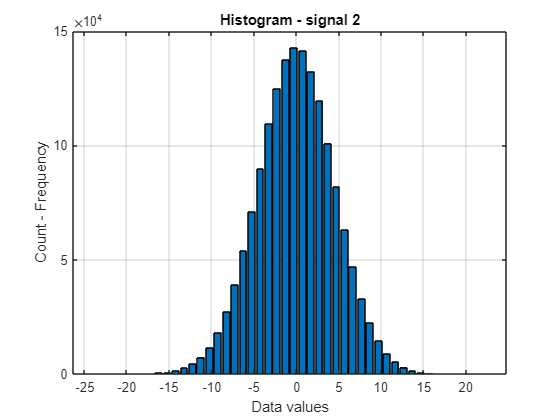



% Plotting Histogram for analysing the frequecny of value occured
figure(8);
nclasses=50;
[count_2, centre_2] = hist(signal_2, nclasses);
bar(centre_2, count_2);
grid on;
title('Histogram - signal 2');
xlabel('Data values');
ylabel('Count - Frequency');

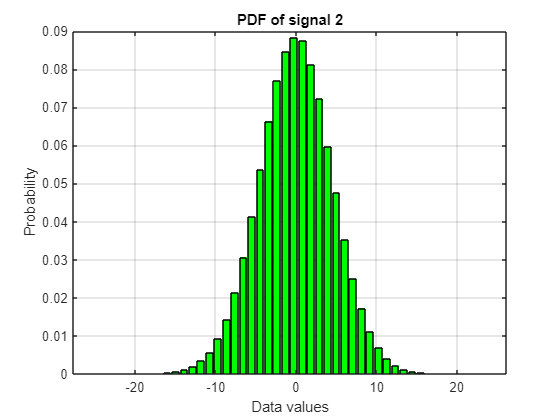


% Plotting Probability density function
figure(9);
nclasses=50;
[prop_freq_2,ks_center_2] = ksdensity(signal_2,'npoints', nclasses);
bar(ks_center_2, prop_freq_2, 'g');
grid on;
title('PDF of signal 2');
xlabel('Data values');
ylabel('Probability');

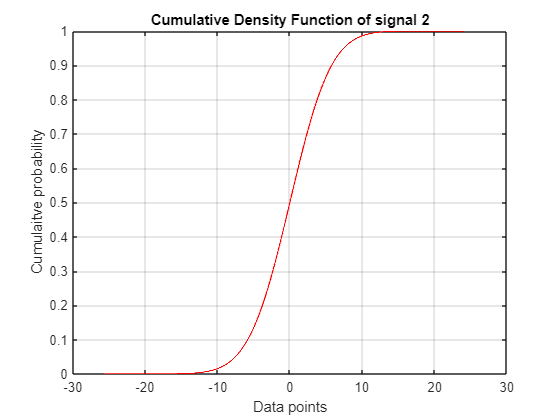


% Plotting Cumulative density function
figure(10);
[fcdf_2,xcdf_2] = ecdf(signal_2);
plot(xcdf_2,fcdf_2, 'r','LineWidth',1);
grid on;
title('Cumulative Density Function of signal 2')
xlabel('Data points');
ylabel('Cumulaitve probability');

**Analysis of Signal 3**

% Loading signal 3
% Construct the full path of the selected file
File_Path = fullfile(savepath, signal3);

% Load the data from the selected file
loadedData = load(File_Path);

% Extracting the only the datensatz details from the signal
signal_3 = loadedData.datensatz;

mean_Signal_3 = mean(signal_3) % Mean

mean_Signal_3 = -0.0248

RMS_Signal_3 = rms(signal_3) % Root mean square

RMS_Signal_3 = 14.4015

STD_Signal_3 = std(signal_3) % standard deviation

STD_Signal_3 = 14.4015

var_Signal_3 = var(signal_3) % variance

var_Signal_3 = 207.4042

skew_Signal_3 = skewness(signal_3) % skewness

skew_Signal_3 = 0.0480

crest_Signal_3 = peak2rms(signal_3) % Crest 

crest_Signal_3 = 3.7878

Kurto_Signal_3 = kurtosis(signal_3) % kurtosis

Kurto_Signal_3 = 2.4084

quant50_Signal_3 = quantile(signal_3,0.5) % Quantile for 50% of the signal

quant50_Signal_3 = -0.2171

quant95_Signal_3 = quantile(signal_3,0.95) % Quantile for 95% of the signal

quant95_Signal_3 = 23.2616

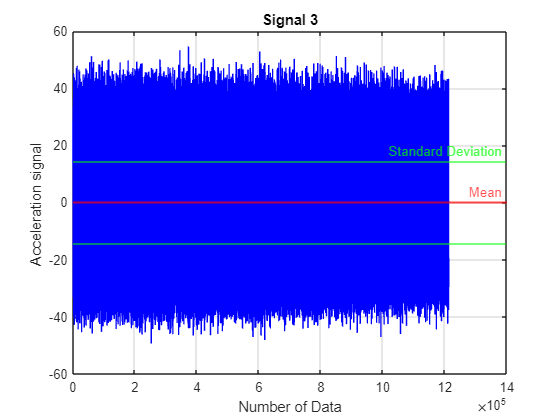


% Plotting the Signal
figure(11)
plot(signal_3, 'b');
grid on
xlabel('Number of Data');
ylabel('Acceleration signal ');
yline(mean_Signal_3,'r','Mean','LineWidth',1.5,'FontSize',10);
yline(STD_Signal_3,'g', 'Standard Deviation');
yline(-STD_Signal_3,'g');
title('Signal 3');

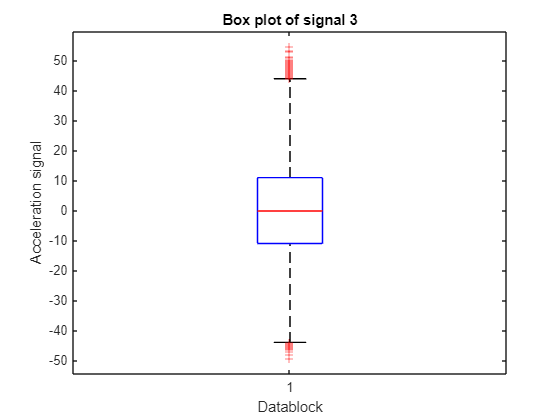


% Plotting box plot for the signal
figure(12)
boxplot(signal_3)
title('Box plot of signal 3')
xlabel('Datablock')
ylabel('Acceleration signal')

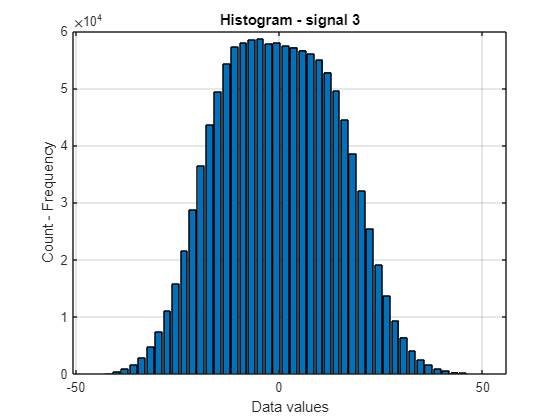



% Plotting Histogram for analysing the frequecny of value occured
figure(13);
nclasses=50;
[count_3, centre_3] = hist(signal_3, nclasses);
bar(centre_3, count_3);
grid on;
title('Histogram - signal 3');
xlabel('Data values');
ylabel('Count - Frequency');

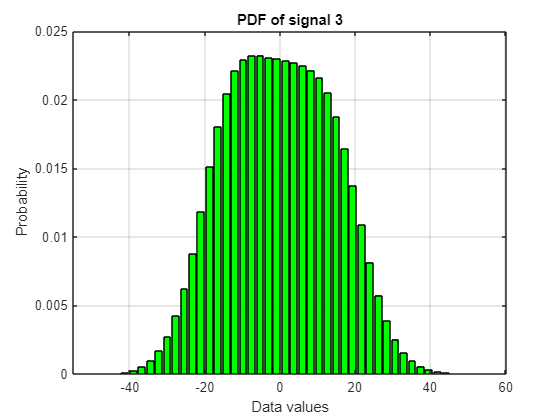


% Plotting Probability density function
figure(14);
nclasses=50;
[prop_freq_3,ks_center_3] = ksdensity(signal_3,'npoints', nclasses);
bar(ks_center_3, prop_freq_3, 'g');
grid on;
title('PDF of signal 3');
xlabel('Data values');
ylabel('Probability');

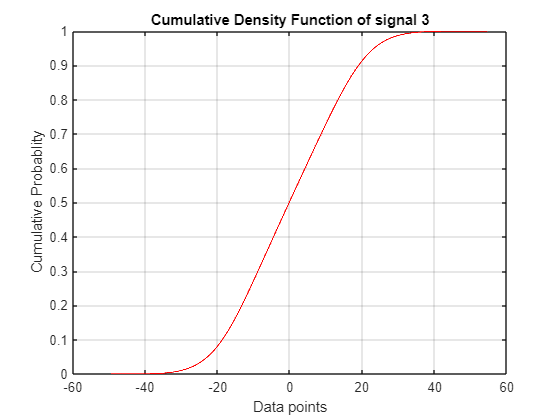


% Plotting Cumulative density function
figure(15);
[fcdf_3,xcdf_3] = ecdf(signal_3);
plot(xcdf_3,fcdf_3, 'r','LineWidth',1);
grid on;
title('Cumulative Density Function of signal 3')
xlabel('Data points');
ylabel('Cumulative Probablity');

**Viewing the features of the signals in a single plot:**

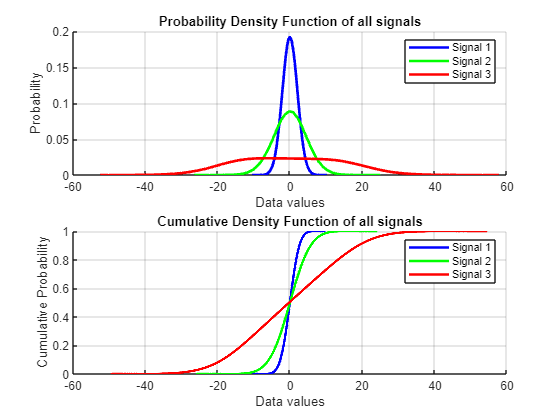

% Plotting the Probability Density Funsitions of all the three signals
figure(16)
subplot(2, 1, 1);
grid on;
hold on;
plot(ks_center_1, prop_freq_1, 'b','LineWidth',2);
plot(ks_center_2, prop_freq_2, 'g','LineWidth',2);
plot(ks_center_3, prop_freq_3, 'r','LineWidth',2);
title('Probability Density Function of all signals')
xlabel('Data values');
ylabel('Probability');
legend('Signal 1','Signal 2','Signal 3');
hold off;


% Plotting the Cumulative Density Funsitions of all the three signals
subplot(2, 1, 2);
grid on;
hold on;
plot(xcdf_1,fcdf_1, 'b','LineWidth',2);
plot(xcdf_2,fcdf_2, 'g','LineWidth',2);
plot(xcdf_3,fcdf_3, 'r','LineWidth',2);
title('Cumulative Density Function of all signals')
xlabel('Data values');
ylabel('Cumulative Probability');
legend('Signal 1','Signal 2','Signal 3');
hold off;

## **2. ****Analysis of signals in Frequency domain**

Given are the following parameters:

datensatz - Acceleration signal;

fs - sampling frequency in Hz;

fn - Rotational frequency of the bearing in Hz;

First the following signals are converted into frequency domain by means of  fourier transform, by the function FFT (fast fourier transform) in the matlab.

**Analysing Signal 1:**

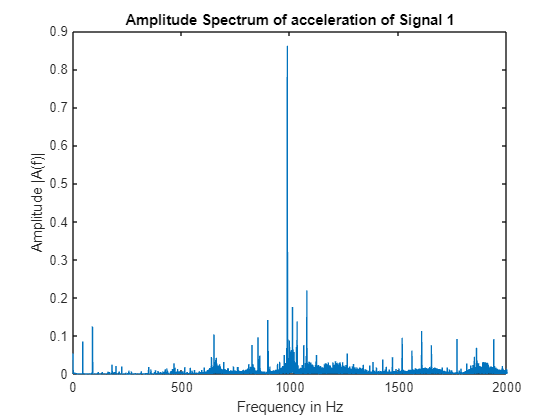

% Loading signal 1
% Construct the full path of the selected file
File_Path = fullfile(savepath, signal1);

% Load the data from the selected file
loadedData = load(File_Path);

% Extracting the only the datensatz details from the signal
signal_1 = loadedData.datensatz;
fn_1 = loadedData.fn;

% Sample frequency in the given
fs = 40000;

% Fourier Transform
X_1 =  fft(signal_1);
% Number of samples
N = length(signal_1);
% Finding the discrete frequency step
df = fs/N;

% Frequency axis with consideration of mirror frequencies
freqend = ((N-1)*df)/2;
freq = (0:df:freqend);

% Finding the amplitude of the signal in frequency domain using Power
% spectral density
X_1_amp = ((sqrt(X_1.*conj(X_1)))*df*2)/fs;
X_1_amp = X_1_amp(1:N/2);

figure(17)
plot(freq,X_1_amp);
title('Amplitude Spectrum of acceleration of Signal 1');
xlabel('Frequency in Hz');
ylabel('Amplitude |A(f)|');
xlim([0 2000])

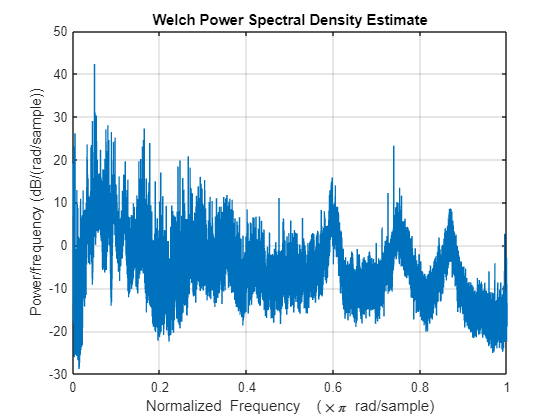


figure(18)
pwelch(signal_1);

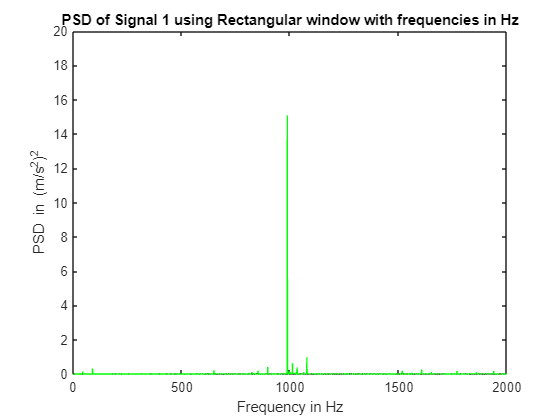


% Signal after windowing using rectangular window
figure(19)
[S_1,f_1] = pwelch(signal_1,window(@rectwin,N),[],N,fs);
plot(f_1,S_1,'g');
xlim([0 2000]);
ylim([0 20]);
title('PSD of Signal 1 using Rectangular window with frequencies in Hz');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');

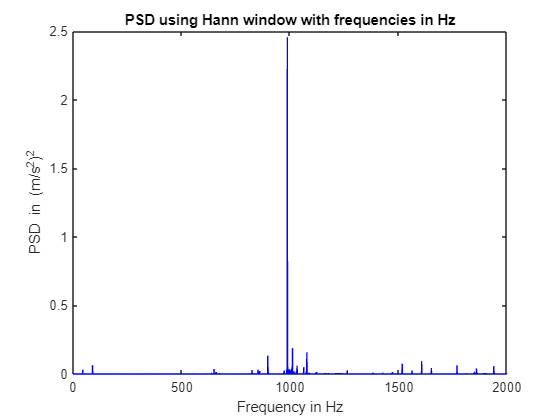


% Signal after windowing using Hann window
figure(20)
winleng = floor(N/4.5); % rounding off to the nearest decimel using floor function
noverlap = floor(winleng/2);
nfft = 2^22;
[S_han1,f_han1] = pwelch(signal_1,window(@hann,winleng),noverlap,nfft,fs);
plot(f_han1,S_han1, 'b')
xlim([0 2000]);
title('PSD using Hann window with frequencies in Hz')
xlabel('Frequency in Hz')
ylabel('PSD in (m/s^2)^2')

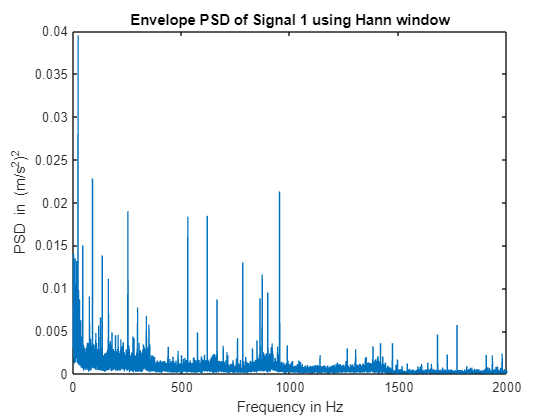


%Using Hilberts transform to form a envelope and applying Hann window
figure(21)
h = hcurve_fun(signal_1,1,N);
[S_env_1,f_env_1] = pwelch(h,window(@hann,winleng),noverlap,nfft,fs);
plot(f_env_1(50:end,1),2*S_env_1(50:end)) % starting from first 50 frequency as the 0th frequency supress others
xlim([0 2000]);
title('Envelope PSD of Signal 1 using Hann window')
xlabel('Frequency in Hz')
ylabel('PSD in (m/s^2)^2')

**Damage Frequencies of the bearing: signal 1**

The bearing of the type SKF 61804 is a single row rill ball bearing with a cage and thirteen balls. The exact name of the bearing from the company SKF is. (SKF 61804 055C PK12).

The geometric parameters are

- Number of rolling elements = 13

- Diameter of the rolling elements = 3.7 mm

- Part - circle diameter = 26.15 mm

- Operating contact angle = 0 degree

- Rotational Frequency = 50 Hz

The damage frequencies of different types are found using the formulae stated in the description PDF

% Given geometric parameters
nWK = 13;
DW = 3.7;
DT = 26.15;
alpha = 0;

% Cage rotational frequency with fix outer ring
crf_or_1 = 0.5*fn_1*(1-(DW*cos(alpha)/DT));

% Cage rotational frequency with fix inner ring
crf_ir_1= 0.5*fn_1*(1+(DW*cos(alpha)/DT));

% Rollover frequency of an irregularity on the outer ring
rfi_or_1 = 0.5*fn_1*nWK*(1-(DW*cos(alpha)/DT));

% Rollover frequency of an irregularity on the inner ring
rfi_ir_1= 0.5*fn_1*nWK*(1+(DW*cos(alpha)/DT));

% Rolling element rotation frequency or rolling element spin frequency
resf_1= 0.5*fn_1*(DT/DW)*(1-(DW*cos(alpha)/DT)^2);

% Rollover frequency of a rolling element irregularity on both tracks
rfi_bt_1= fn_1*(DT/DW)*(1-(DW*cos(alpha)/DT)^2);

**Analysing Signal 2:**

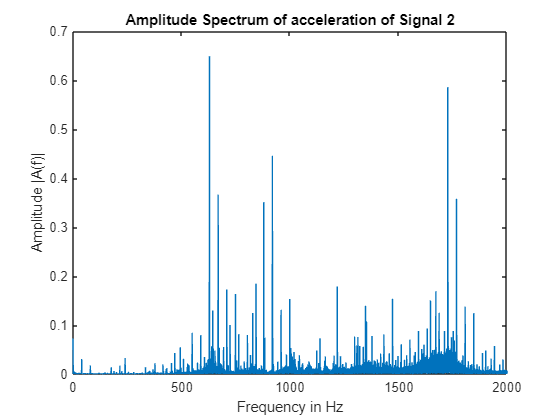

% Loading signal 2
% Construct the full path of the selected file
File_Path = fullfile(savepath, signal2);

% Load the data from the selected file
loadedData = load(File_Path);

% Extracting the only the datensatz details from the signal
signal_2 = loadedData.datensatz;
fn_2 = loadedData.fn;

% Sample frequency in the given
fs = 40000;

% Fourier Transform
X_2 =  fft(signal_2);
% Number of samples
N_2 = length(signal_2);
% Finding the discrete frequency step
df = fs/N_2;

% Frequency axis with consideration of mirror frequencies
freqend = ((N_2-1)*df)/2;
freq = (0:df:freqend);

% Finding the amplitude of the signal in frequency domain using Power
% spectral density
X_2_amp = ((sqrt(X_2.*conj(X_2)))*df*2)/fs;
N_2 = floor(N_2/2) +1 ;
X_2_amp = X_2_amp(1:N_2);

figure(22)
plot(freq,X_2_amp);
title('Amplitude Spectrum of acceleration of Signal 2');
xlabel('Frequency in Hz');
ylabel('Amplitude |A(f)|');
xlim([0 2000])

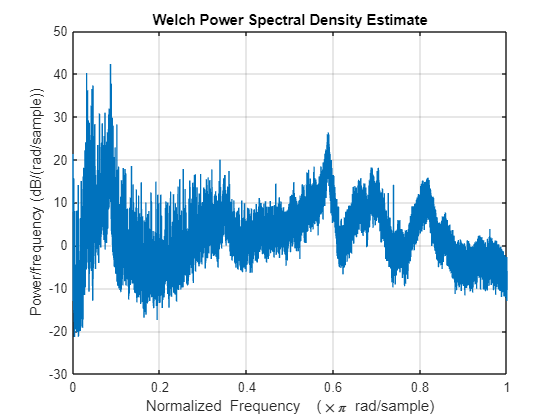


figure(23)
pwelch(signal_2);

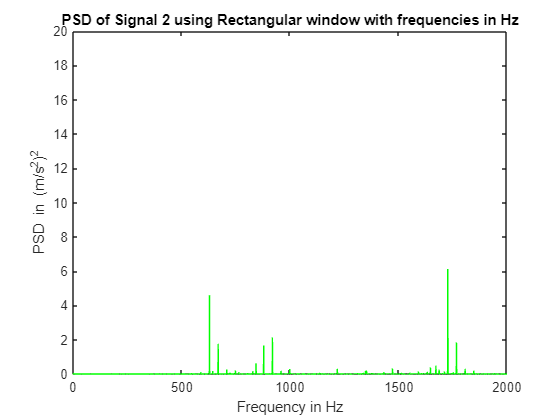


% Signal after windowing using rectangular window
figure(24)
[S_2,f_2] = pwelch(signal_2,window(@rectwin,N_2),[],N_2,fs);
plot(f_2,S_2,'g');
xlim([0 2000]);
ylim([0 20]);
title('PSD of Signal 2 using Rectangular window with frequencies in Hz');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');

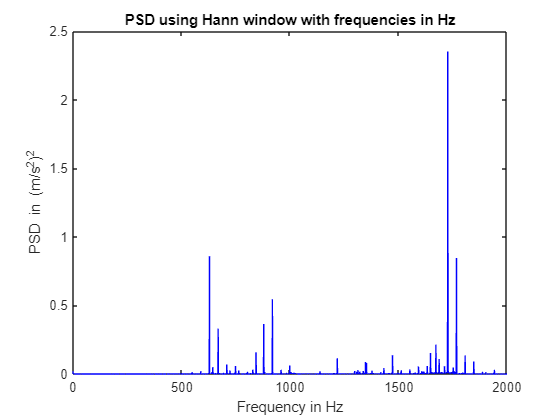


% Signal after windowing using Hann window
figure(25)
winleng = floor(N_2/4.5); % rounding off to the nearest decimel using floor function
noverlap = floor(winleng/2);
nfft = 2^22;
[S_han2,f_han2] = pwelch(signal_2,window(@hann,winleng),noverlap,nfft,fs);
plot(f_han2,S_han2, 'b')
xlim([0 2000]);
title('PSD using Hann window with frequencies in Hz')
xlabel('Frequency in Hz')
ylabel('PSD in (m/s^2)^2')

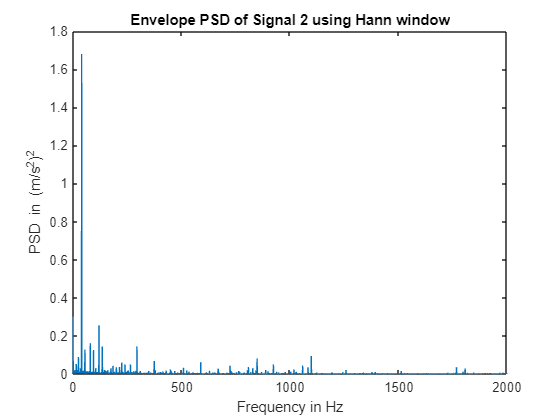


%Using Hilberts transform to form a envelope and applying Hann window
figure(26)
h = hcurve_fun(signal_2,1,N_2);
[S_env_2,f_env_2] = pwelch(h,window(@hann,winleng),noverlap,nfft,fs);
plot(f_env_2(50:end,1),2*S_env_2(50:end)) % starting from first 50 frequency as the 0th frequency supress others
xlim([0 2000]);
title('Envelope PSD of Signal 2 using Hann window')
xlabel('Frequency in Hz')
ylabel('PSD in (m/s^2)^2')

**Damage Frequencies of the bearing: signal 2**

The damage frequencies of different types are found using the formulae stated in the description PDF

% Given geometric parameters
nWK = 13;
DW = 3.7;
DT = 26.15;
alpha = 0;

% Cage rotational frequency with fix outer ring
crf_or_2 = 0.5*fn_2*(1-(DW*cos(alpha)/DT));

% Cage rotational frequency with fix inner ring
crf_ir_2= 0.5*fn_2*(1+(DW*cos(alpha)/DT));

% Rollover frequency of an irregularity on the outer ring
rfi_or_2 = 0.5*fn_2*nWK*(1-(DW*cos(alpha)/DT));

% Rollover frequency of an irregularity on the inner ring
rfi_ir_2 = 0.5*fn_2*nWK*(1+(DW*cos(alpha)/DT));

% Rolling element rotation frequency or rolling element spin frequency
resf_2 = 0.5*fn_2*(DT/DW)*(1-(DW*cos(alpha)/DT)^2);

% Rollover frequency of a rolling element irregularity on both tracks
rfi_bt_2 = fn_2*(DT/DW)*(1-(DW*cos(alpha)/DT)^2);

**Analysing Signal 3:**

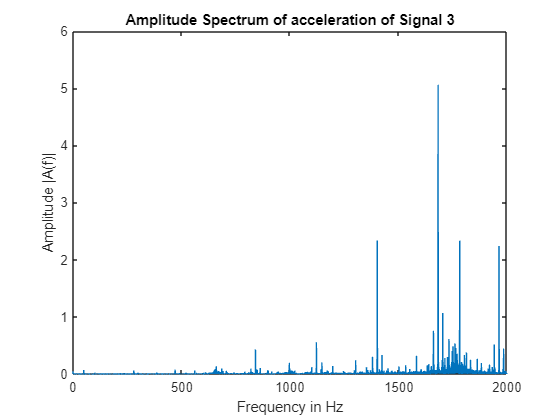

% Loading signal 3
% Construct the full path of the selected file
File_Path = fullfile(savepath, signal3);

% Load the data from the selected file
loadedData = load(File_Path);

% Extracting the only the datensatz details from the signal
signal_3 = loadedData.datensatz;
fn_3 = loadedData.fn;

% Sample frequency in the given
fs = 40000;

% Fourier Transform
X_3 =  fft(signal_3);
% Number of samples
N_3 = length(signal_3);
% Finding the discrete frequency step
df = fs/N_3;

% Frequency axis with consideration of mirror frequencies
freqend = ((N_3-1)*df)/2;
freq = (0:df:freqend);

% Finding the amplitude of the signal in frequency domain using Power
% spectral density
X_3_amp = ((sqrt(X_3.*conj(X_3)))*df*2)/fs;
N_3= floor(N_3/2) + 1;
X_3_amp = X_3_amp(1:N_3);

figure(27)
plot(freq,X_3_amp);
title('Amplitude Spectrum of acceleration of Signal 3');
xlabel('Frequency in Hz');
ylabel('Amplitude |A(f)|');
xlim([0 2000])

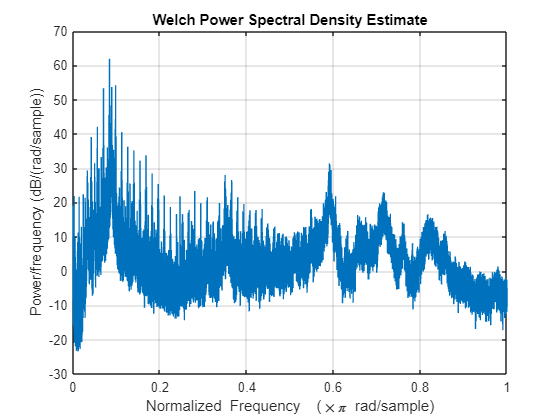


figure(28)
pwelch(signal_3);

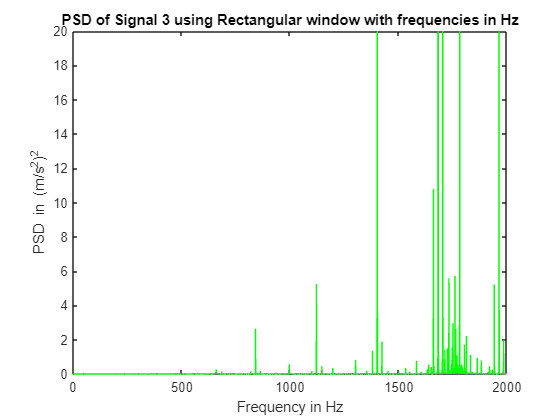


% Signal after windowing using rectangular window
figure(29)
[S_3,f_3] = pwelch(signal_3,window(@rectwin,N_3),[],N_3,fs);
plot(f_3,S_3,'g');
xlim([0 2000]);
ylim([0 20]);
title('PSD of Signal 3 using Rectangular window with frequencies in Hz');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');

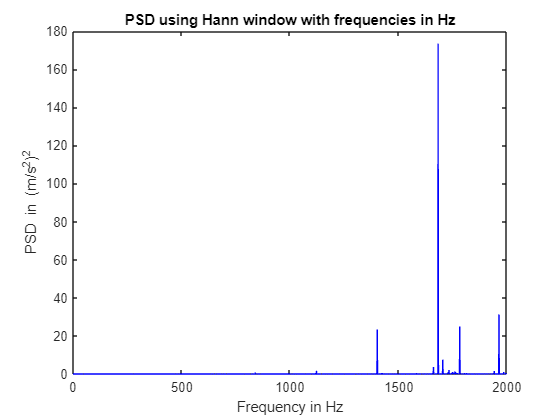


% Signal after windowing using Hann window
figure(30)
winleng = floor(N_3/4.5); % rounding off to the nearest decimel using floor function
noverlap = floor(winleng/2);
nfft = 2^22;
[S_han3,f_han3] = pwelch(signal_3,window(@hann,winleng),noverlap,nfft,fs);
plot(f_han3,S_han3,'b')
xlim([0 2000]);
title('PSD using Hann window with frequencies in Hz')
xlabel('Frequency in Hz')
ylabel('PSD in (m/s^2)^2')

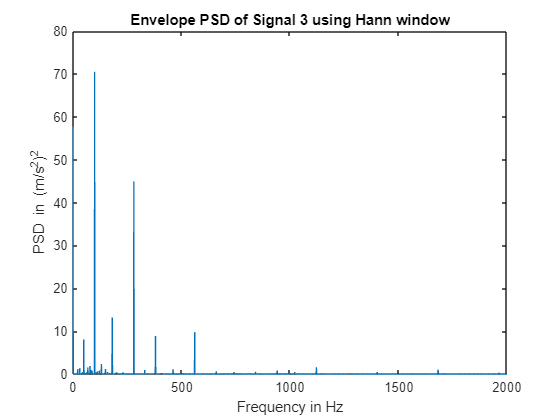


%Using Hilberts transform to form a envelope and applying Hann window
figure(31)
h = hcurve_fun(signal_3,1,N_3);
[S_env_3,f_env_3] = pwelch(h,window(@hann,winleng),noverlap,nfft,fs);
plot(f_env_3(50:end,1),2*S_env_3(50:end)) % starting from first 50 frequency as the 0th frequency supress others
xlim([0 2000]);
title('Envelope PSD of Signal 3 using Hann window')
xlabel('Frequency in Hz')
ylabel('PSD in (m/s^2)^2')

**Damage Frequencies of the bearing: signal 3**

The damage frequencies of different types are found using the formulae stated in the description PDF

% Given geometric parameters
nWK = 13;
DW = 3.7;
DT = 26.15;
alpha = 0;

% Cage rotational frequency with fix outer ring
crf_or_3 = 0.5*fn_3*(1-(DW*cos(alpha)/DT));

% Cage rotational frequency with fix inner ring
crf_ir_3= 0.5*fn_3*(1+(DW*cos(alpha)/DT));

% Rollover frequency of an irregularity on the outer ring
rfi_or_3 = 0.5*fn_3*nWK*(1-(DW*cos(alpha)/DT));

% Rollover frequency of an irregularity on the inner ring
rfi_ir_3 = 0.5*fn_3*nWK*(1+(DW*cos(alpha)/DT));

% Rolling element rotation frequency or rolling element spin frequency
resf_3 = 0.5*fn_3*(DT/DW)*(1-(DW*cos(alpha)/DT)^2);

% Rollover frequency of a rolling element irregularity on both tracks
rfi_bt_3 = fn_3*(DT/DW)*(1-(DW*cos(alpha)/DT)^2);

**Comparing the Envelope PSD witht the harmonics of the damage frequencies and Predicting the type of damage occured:**

**Comparing Signal 1 frequencies with damaged frequency:**

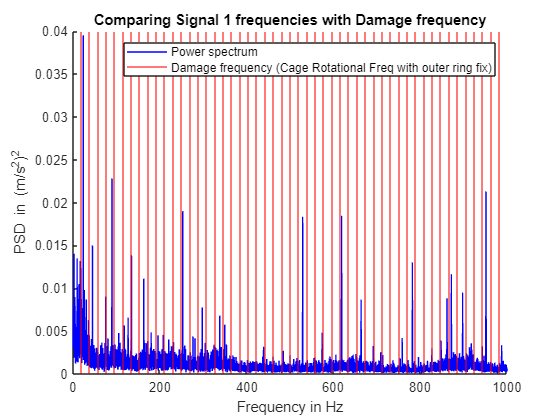

figure(32)
hold on
plot(f_env_1(50:end,1),2*S_env_1(50:end),'b') % starting from first 50 frequency as the 0th frequency supress others
xlim([0 2000]);
harmonics_11 = (1:200)*crf_or_1;
xline(harmonics_11, 'r');
xlim([0,1000]);
title('Comparing Signal 1 frequencies with Damage frequency');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');
legend('Power spectrum', 'Damage frequency (Cage Rotational Freq with outer ring fix)');
hold off

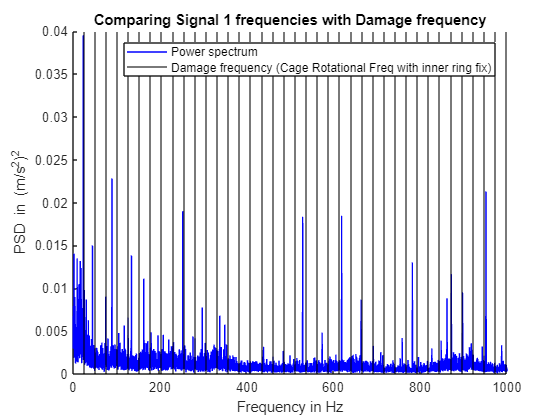


figure(33)
hold on
plot(f_env_1(50:end,1),2*S_env_1(50:end),'b') % starting from first 50 frequency as the 0th frequency supress others
harmonics_12 = (1:50)*crf_ir_1;
xline(harmonics_12, 'k');
xlim([0,1000]);
title('Comparing Signal 1 frequencies with Damage frequency');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');
legend('Power spectrum', 'Damage frequency (Cage Rotational Freq with inner ring fix)');
hold off

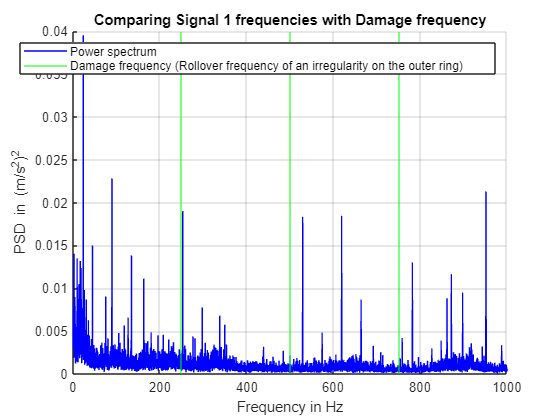


figure(34)
grid on
hold on
plot(f_env_1(50:end,1),2*S_env_1(50:end),'b') % starting from first 50 frequency as the 0th frequency supress others
harmonics_13 = (1:50)*rfi_or_1;
xline(harmonics_13, 'g');
xlim([0,1000]);
title('Comparing Signal 1 frequencies with Damage frequency');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');
legend('Power spectrum', 'Damage frequency (Rollover frequency of an irregularity on the outer ring)');
hold off

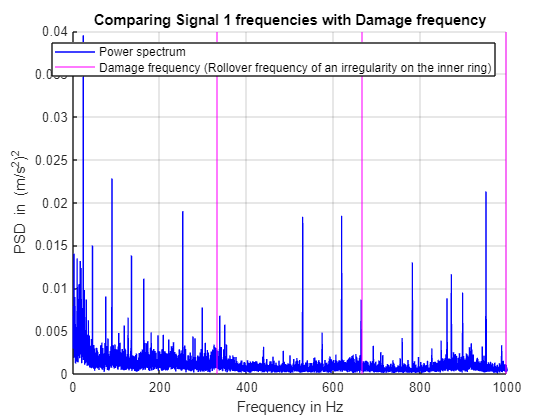


figure(35)
grid on
hold on
plot(f_env_1(50:end,1),2*S_env_1(50:end),'b') % starting from first 50 frequency as the 0th frequency supress others
harmonics_14 = (1:50)*rfi_ir_1;
xline(harmonics_14, 'm');
xlim([0,1000]);
title('Comparing Signal 1 frequencies with Damage frequency');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');
legend('Power spectrum', 'Damage frequency (Rollover frequency of an irregularity on the inner ring)');
hold off

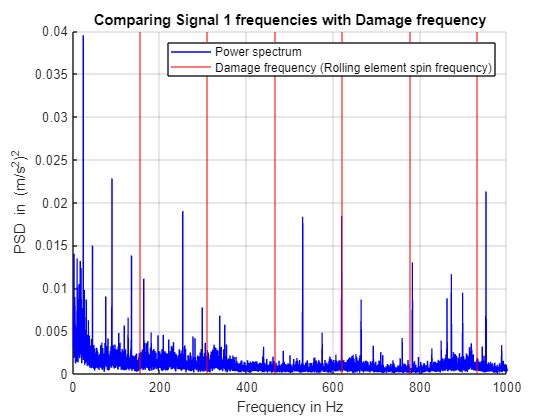


figure(36)
grid on
hold on
plot(f_env_1(50:end,1),2*S_env_1(50:end),'b') % starting from first 50 frequency as the 0th frequency supress others
xlim([0 2000]);
harmonics_15 = (1:50)*resf_1;
xline(harmonics_15, 'r');
xlim([0,1000]);
title('Comparing Signal 1 frequencies with Damage frequency');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');
legend('Power spectrum', 'Damage frequency (Rolling element spin frequency)');
hold off

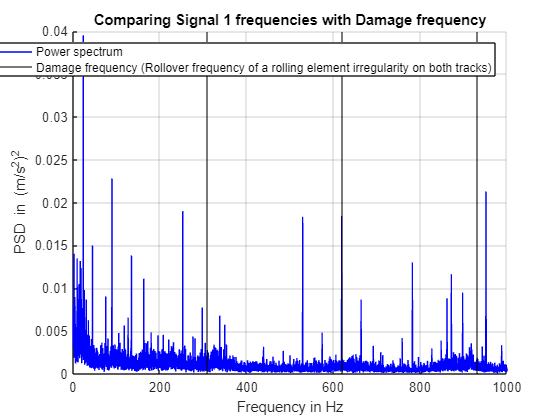


figure(37)
grid on
hold on
plot(f_env_1(50:end,1),2*S_env_1(50:end),'b') % starting from first 50 frequency as the 0th frequency supress others
harmonics_16 = (1:50)*rfi_bt_1;
xline(harmonics_16, 'k');
xlim([0,1000]);
title('Comparing Signal 1 frequencies with Damage frequency');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');
legend('Power spectrum', 'Damage frequency (Rollover frequency of a rolling element irregularity on both tracks)');
hold off

**Comparing Signal 2 frequencies with damaged frequency:**

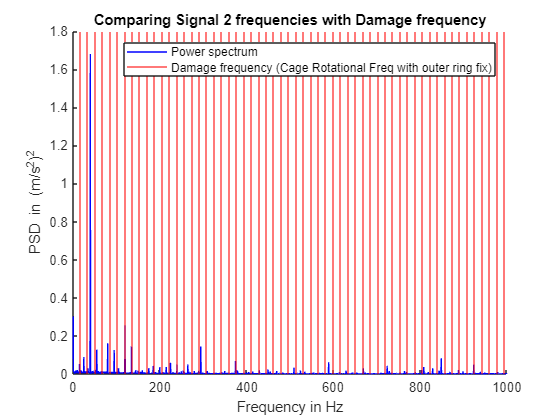

figure(38)
hold on
plot(f_env_2(50:end,1),2*S_env_2(50:end),'b') % starting from first 50 frequency as the 0th frequency supress others
xlim([0 2000]);
harmonics_21 = (1:200)*crf_or_2;
xline(harmonics_21, 'r');
xlim([0,1000]);
title('Comparing Signal 2 frequencies with Damage frequency');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');
legend('Power spectrum', 'Damage frequency (Cage Rotational Freq with outer ring fix)');
hold off

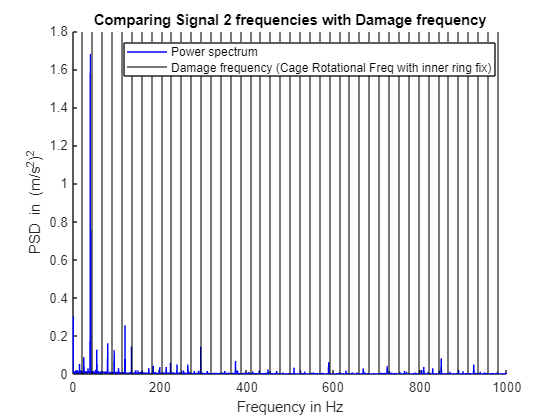


figure(39)
hold on
plot(f_env_2(50:end,1),2*S_env_2(50:end),'b') % starting from first 50 frequency as the 0th frequency supress others
harmonics_22 = (1:50)*crf_ir_2;
xline(harmonics_22, 'k');
xlim([0,1000]);
title('Comparing Signal 2 frequencies with Damage frequency');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');
legend('Power spectrum', 'Damage frequency (Cage Rotational Freq with inner ring fix)');
hold off

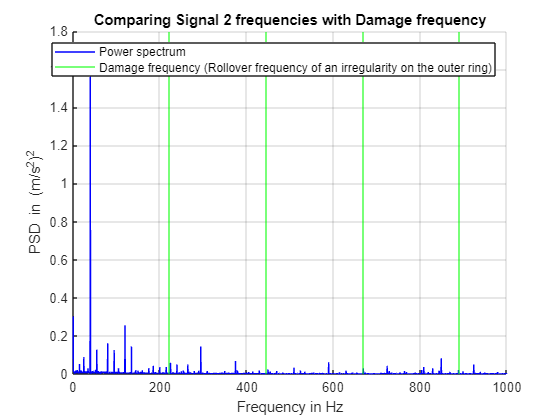


figure(40)
grid on
hold on
plot(f_env_2(50:end,1),2*S_env_2(50:end),'b') % starting from first 50 frequency as the 0th frequency supress others
harmonics_23 = (1:50)*rfi_or_2;
xline(harmonics_23, 'g');
xlim([0,1000]);
title('Comparing Signal 2 frequencies with Damage frequency');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');
legend('Power spectrum', 'Damage frequency (Rollover frequency of an irregularity on the outer ring)');
hold off

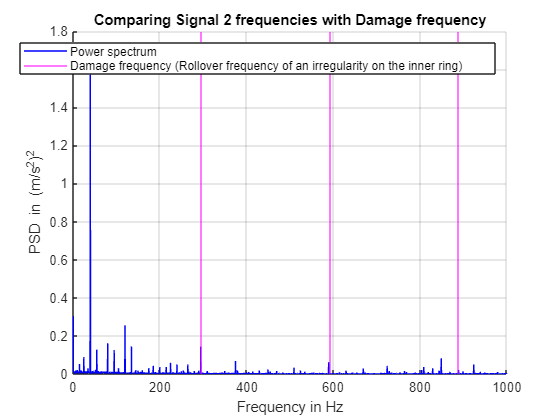


figure(41)
grid on
hold on
plot(f_env_2(50:end,1),2*S_env_2(50:end),'b') % starting from first 50 frequency as the 0th frequency supress others
harmonics_24 = (1:50)*rfi_ir_2;
xline(harmonics_24, 'm');
xlim([0,1000]);
title('Comparing Signal 2 frequencies with Damage frequency');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');
legend('Power spectrum', 'Damage frequency (Rollover frequency of an irregularity on the inner ring)');
hold off

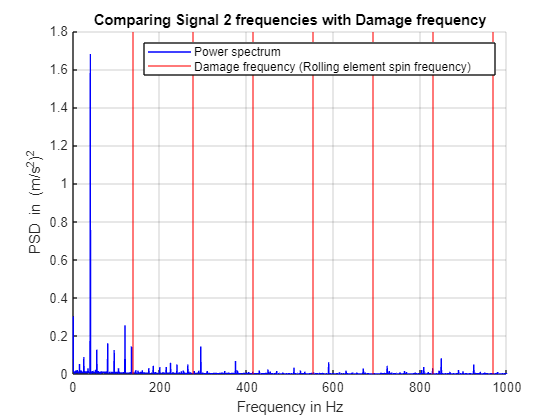


figure(42)
grid on
hold on
plot(f_env_2(50:end,1),2*S_env_2(50:end),'b') % starting from first 50 frequency as the 0th frequency supress others
xlim([0 2000]);
harmonics_25 = (1:50)*resf_2;
xline(harmonics_25, 'r');
xlim([0,1000]);
title('Comparing Signal 2 frequencies with Damage frequency');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');
legend('Power spectrum', 'Damage frequency (Rolling element spin frequency)');
hold off

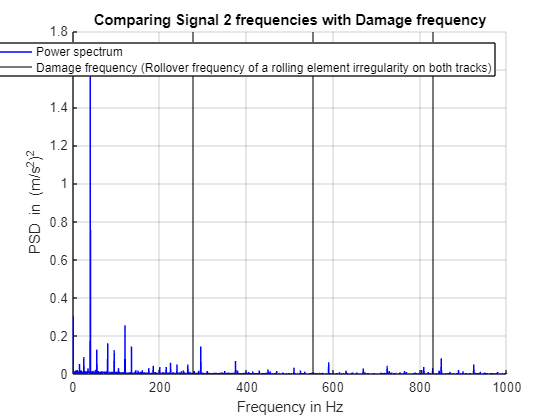


figure(43)
grid on
hold on
plot(f_env_2(50:end,1),2*S_env_2(50:end),'b') % starting from first 50 frequency as the 0th frequency supress others
harmonics_26 = (1:50)*rfi_bt_2;
xline(harmonics_26, 'k');
xlim([0,1000]);
title('Comparing Signal 2 frequencies with Damage frequency');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');
legend('Power spectrum', 'Damage frequency (Rollover frequency of a rolling element irregularity on both tracks)');
hold off

**Comparing Signal 3 frequencies with damaged frequency:**

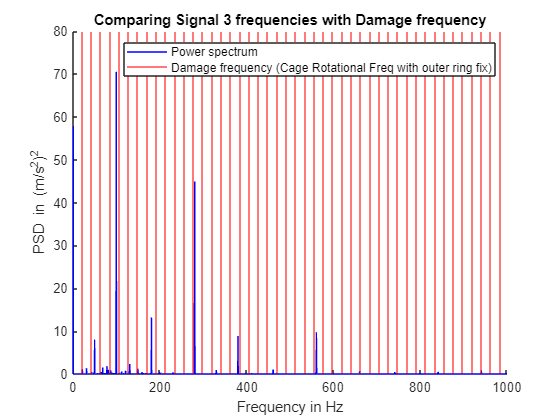

figure(44)
hold on
plot(f_env_3(50:end,1),2*S_env_3(50:end),'b') % starting from first 50 frequency as the 0th frequency supress others
xlim([0 2000]);
harmonics_31 = (1:200)*crf_or_3;
xline(harmonics_31, 'r');
xlim([0,1000]);
title('Comparing Signal 3 frequencies with Damage frequency');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');
legend('Power spectrum', 'Damage frequency (Cage Rotational Freq with outer ring fix)');
hold off

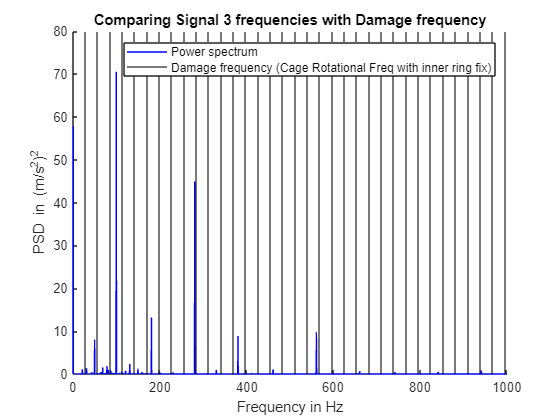


figure(45)
hold on
plot(f_env_3(50:end,1),2*S_env_3(50:end),'b') % starting from first 50 frequency as the 0th frequency supress others
harmonics_32 = (1:50)*crf_ir_3;
xline(harmonics_32, 'k');
xlim([0,1000]);
title('Comparing Signal 3 frequencies with Damage frequency');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');
legend('Power spectrum', 'Damage frequency (Cage Rotational Freq with inner ring fix)');
hold off

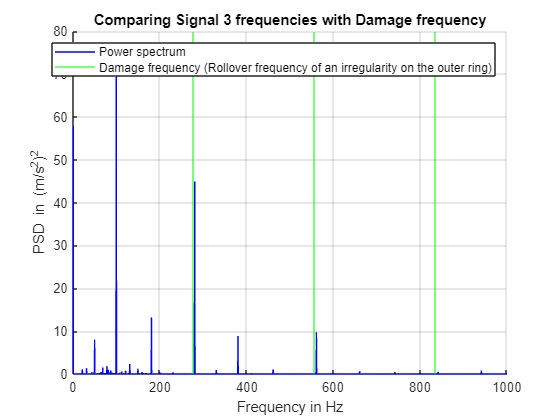


figure(46)
grid on
hold on
plot(f_env_3(50:end,1),2*S_env_3(50:end),'b') % starting from first 50 frequency as the 0th frequency supress others
harmonics_33 = (1:50)*rfi_or_3;
xline(harmonics_33, 'g');
xlim([0,1000]);
title('Comparing Signal 3 frequencies with Damage frequency');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');
legend('Power spectrum', 'Damage frequency (Rollover frequency of an irregularity on the outer ring)');
hold off

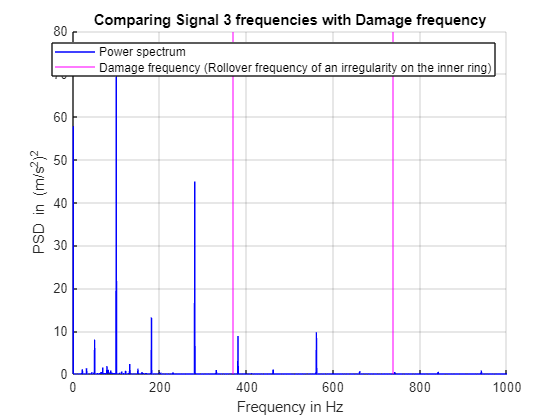


figure(47)
grid on
hold on
plot(f_env_3(50:end,1),2*S_env_3(50:end),'b') % starting from first 50 frequency as the 0th frequency supress others
harmonics_34 = (1:50)*rfi_ir_3;
xline(harmonics_34, 'm');
xlim([0,1000]);
title('Comparing Signal 3 frequencies with Damage frequency');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');
legend('Power spectrum', 'Damage frequency (Rollover frequency of an irregularity on the inner ring)');
hold off

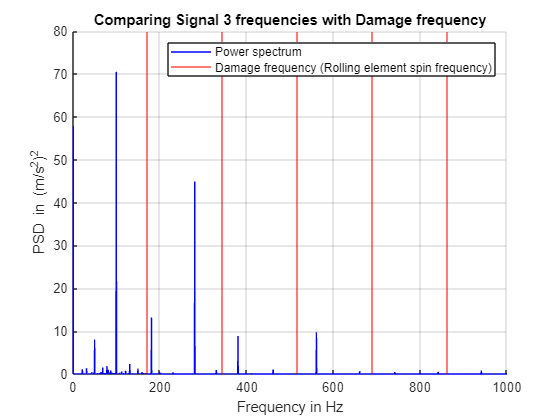


figure(48)
grid on
hold on
plot(f_env_3(50:end,1),2*S_env_3(50:end),'b') % starting from first 50 frequency as the 0th frequency supress others
xlim([0 2000]);
harmonics_35 = (1:50)*resf_3;
xline(harmonics_35, 'r');
xlim([0,1000]);
title('Comparing Signal 3 frequencies with Damage frequency');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');
legend('Power spectrum', 'Damage frequency (Rolling element spin frequency)');
hold off

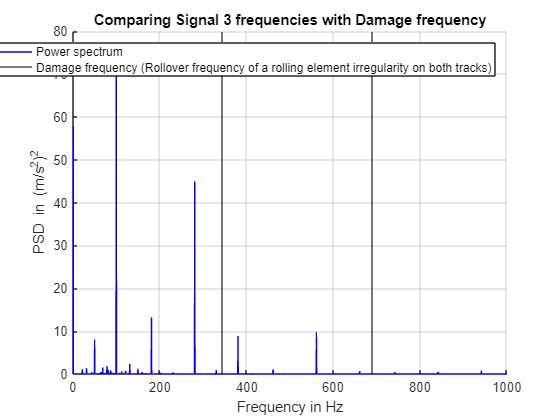


figure(49)
grid on
hold on
plot(f_env_3(50:end,1),2*S_env_3(50:end),'b') % starting from first 50 frequency as the 0th frequency supress others
harmonics_36 = (1:50)*rfi_bt_3;
xline(harmonics_36, 'k');
xlim([0,1000]);
title('Comparing Signal 3 frequencies with Damage frequency');
xlabel('Frequency in Hz');
ylabel('PSD in (m/s^2)^2');
legend('Power spectrum', 'Damage frequency (Rollover frequency of a rolling element irregularity on both tracks)');
hold off